# P2. Vehicle Lateral Dynamics

Vehicle Control Systems

Degree in Electronics, Robotics and Mechatronics Engineering

University of Malaga

Created by: David Rodríguez Martínez

Last updated: 28 September 2026

### Introduction and objectives

This file contains the coursework instructions and code blocks to complete. Extend the P1 race-car model with longitudinal and lateral dynamics while retaining the P1 longitudinal control functions.

This exercise requires the lateral equation of motion developed in Block 2 and both kinematic and dynamic bicycle models.

After completing this exercise, you should be able to:

- Implement the kinematic bicycle model, which is purely geometric without sliding, and the dynamic model using tyre forces and cornering stiffness. Together they extend P1's longitudinal model to capture lateral dynamics.

- Simulate a simplified FS Driverless event 2 skidpad: steady-state circular motion.

- Record vehicle yaw rate, lateral acceleration and slip angles as telemetry.

- Compare both models' results.

#### What you will implement

A) The kinematic model (function pasoCinematico)

B) The dynamic model (function pasoDinamico)

### Vehicle and road parameters

p = struct(); 

p.m    = 230;      % mass [kg]
p.g    = 9.81;     % gravity [m/s^2]
p.rho  = 1.225;    % air density [kg/m^3]
p.Cd   = 1.0;      % aerodynamic coefficient
p.Af   = 1.1;      % frontal area [m^2]
p.fr  = 0.022;    % rolling-resistance coefficient
p.Fx_drive_max = 2500;   % maximum driving force [N]
p.Fx_brake_max = 5000;   % maximum braking force [N]
p.theta = 0;      % road inclination [rad]

% Define the parameters needed to describe the vehicle's
% lateral dynamics here.
p.ld = 0.765; % [m] CG to front axle, longitudinal distance
p.lt = 0.765; % [m] CG to rear axle, longitudinal distance
p.lyd = 0.600; % [m] CG to front wheels, lateral distance
p.lyt = 0.600; % [m] CG to rear wheels, lateral distance
p.hcg = 0.230; % [m] centre-of-gravity height
% Wheel coordinates relative to the CG
% Order: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.L = p.ld+p.lt; 
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.td = p.lyd + p.lyt;
p.tt = p.td; 
p.Iz = 130; % [kg m^2] yaw inertia
p.Cad = 35000; % [N/rad] front cornering stiffness
p.Cat = 50000; % [N/rad] rear cornering stiffness --> understeering vehicle
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.nCa = 0.8; 
p.mu_t = 1.5; % rear tyre friction
p.mu_d = 0.95*p.mu_t; % front tyre friction
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];
% Lateral adhesion loss under excess traction demand
p.Kslip = 3; % Rear-wheel lateral-loss intensity
% Time dynamics of lateral loss and recovery
p.tau_slip_loss = 0.03; % loss time constant [s]
p.tau_slip_rec  = 0.50; % recovery time constant [s]
% Adhesion loss under excess braking demand.
% Initial test values, awaiting calibration.
% Two braking modes: normal and approximate lock.
% Illustrative parameters awaiting experimental calibration.
p.brake_slide_ratio = 0.68; % mu_min / mu_base (high-speed limit)
p.v_brake_slide = 15;      % Speed scale [m/s]
p.brake_lock_on = 1.02;    % Entry: demand / nominal capacity
p.brake_lock_off = 0.90;   % Hysteretic exit
p.tau_brake_loss = 0.03;   % Transition to lock-mode target [s]
p.tau_brake_rec = 0.10;    % Recovery under partial brake relief [s]
p.tau_brake_release = 0.01;% Rapid full-release recovery: 95% in 30 ms

% Force allocation
p.Fzd0 = p.m*p.g*p.lt/p.L; % [N] initial front-axle vertical load
p.Fzt0 = p.m*p.g*p.ld/p.L; % [N] initial rear-axle vertical load
p.Fzw0 = [p.Fzd0/2, p.Fzd0/2, p.Fzt0/2, p.Fzt0/2]; % [N] initial vertical load per wheel
p.drive_w = [0, 0, 0.5, 0.5]; % Driving-force allocation during acceleration
p.brake_w = [0.3, 0.3, 0.2, 0.2]; % Longitudinal-force allocation during braking
p.kRoll = 0.5; % front share of roll moment (replace with a suspension model later)

addpath(fullfile(pwd,'Ensayos'));

### Vehicle model

Define the physics of both longitudinal and lateral vehicle motion here.

Important: this exercise defines the complete model that can serve as the basis of the individual project.

Given the current vehicle state, applied driving force and steering angle, calculate where the vehicle will be at the next time step.

Note: initialize the track geometry and controller first.

Ackermann R = 9.12 m  (delta = 9.52 deg)
Radio medido — cinemático: 9.13 m | dinámico: 14.23 m
Subviraje: el dinámico traza 55.9% más radio.
Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):
   cinemático: 2ª vuelta = 4.11 s
   dinámico  : no completa 2 vueltas en Tmax   (¡sale del carril!)


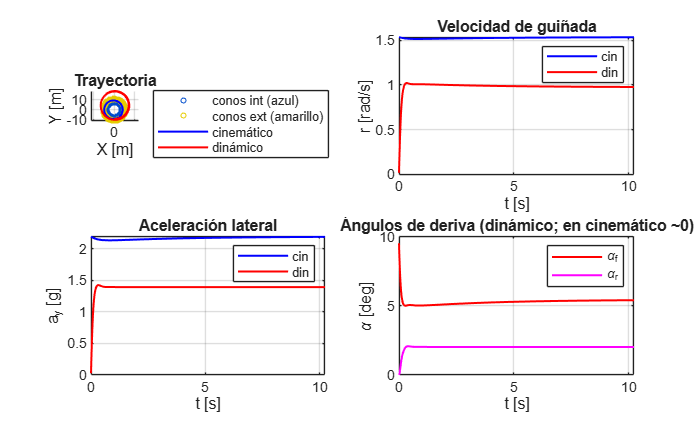

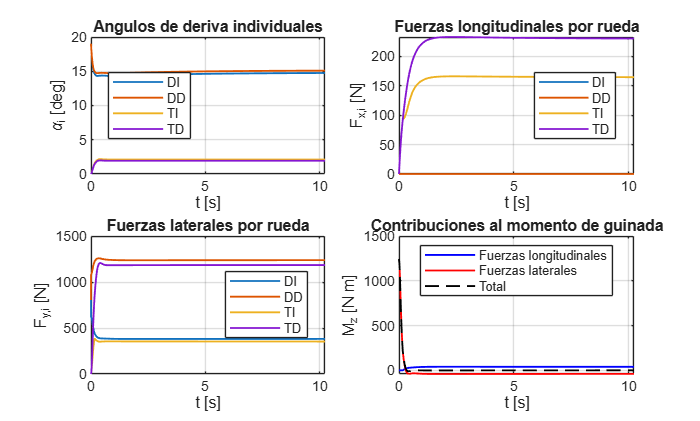

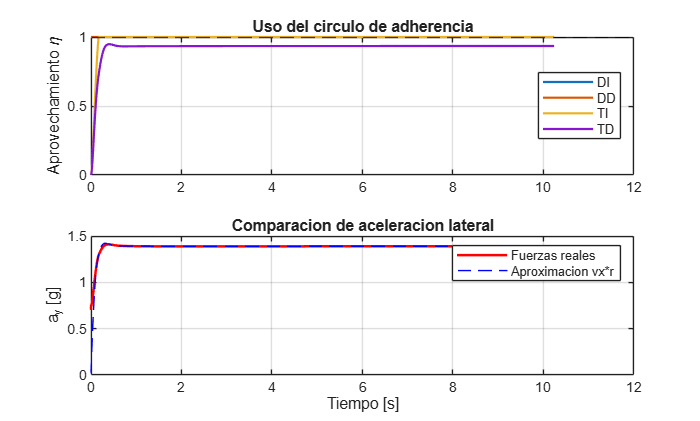

Aprovechamiento maximo por rueda:
    1.0000    1.0000    1.0000    0.9482

Aceleracion lateral maxima: 1.409 g

--- Resumen modelo 4 ruedas ---
Velocidad final: 13.95 m/s
Guiñada final: 0.977 rad/s
Max |deriva| por rueda [deg]: 19.04 19.04 2.17 1.98 
Max |Fx| por rueda [N]: 0.0 0.0 165.6 232.3 
Max |Fy| por rueda [N]: 803.8 1258.1 386.8 1206.8 


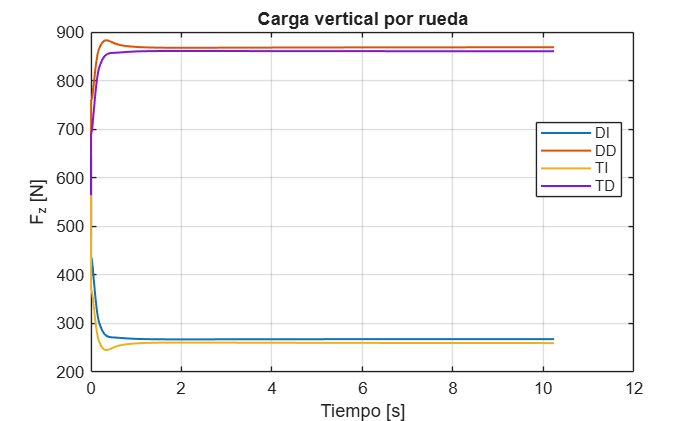

% Longitudinal and lateral dynamics integration

% u: control variable = [Fx; delta]
% z: first 6 components [X; Y; psi; vx; vy; r].
% The dynamic model includes 14 extra memories (see pasoDinamico).
% X, Y = global CG position
% psi = heading / yaw angle
% vx, vy = chassis-frame velocities
% r = yaw rate

% The initial state is defined when simulation starts, after geom and ctrl.

function z_next = pasoCinematico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    L = p.ld + p.lt;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m; % longitudinal equation of motion
    vx_next = max(vx + ax*dt,0);

    %% Lateral dynamics [kinematic]
    beta = atan((p.lt/L)*tan(delta)); % kinematic sideslip angle
    r = (vx/p.lt)*tan(beta);
    vy = vx*tan(beta);

    % transform to global coordinates
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy; r]; % state vector at the next time step

end 

function [z_next, tele] = pasoDinamico(z, u, p, dt)
    % Complete state (20x1), wheel order DI, DD, TI, TD:
    % 1:6   X, Y, psi, vx, vy, r (motion)
    % 7:8   previous ax, ay (quasi-static transfer)
    % 9:12  eta_slip (lateral adhesion memory)
    % 13:16 eta_brake (braking-capacity memory)
    % 17:20 bloqueo_w (discrete mode, 0 or 1)
    if ~isvector(z) || numel(z) ~= 20
        error('pasoDinamico:EstadoInvalido', 'The dynamic state requires 20 components; initialize its memory.');
    end
    z = z(:);
    ax_prev = z(7);
    ay_prev = z(8);
    eta_prev = z(9:12).';
    eta_brake_prev = z(13:16).';
    bloqueo_prev = logical(z(17:20).');
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % corrected speed to avoid division by zero,
    % disabled now that the model uses atan2

    
    %% 1. Individual wheel kinematics

    delta_w = [delta, delta, 0, 0];

    % Wheel-centre velocities in chassis coordinates
    vxw = vx - r .* p.yw;
    vyw = vy + r .* p.xw;

    % Velocities projected into individual wheel coordinates
    vxw_local =  vxw .* cos(delta_w) + vyw .* sin(delta_w);
    vyw_local = -vxw .* sin(delta_w) + vyw .* cos(delta_w);

    % Individual slip angles
    alpha_w = delta_w-atan2(vyw_local, vxw_local);

    %% Define adhesion limits
    % Longitudinal transfer between axles
    dFzx = p.m*ax_prev*p.hcg/p.L;

    % Lateral transfer within each axle
    dFzyd = p.kRoll*p.m*ay_prev*p.hcg/p.td;
    dFzyt = (1-p.kRoll)*p.m*ay_prev*p.hcg/p.tt;

    % Order: DI, DD, TI, TD
    Fzw = p.Fzw0 + [-dFzx/2, -dFzx/2, dFzx/2, dFzx/2] + [-dFzyd, dFzyd, -dFzyt,dFzyt];
    % Longitudinal grip
    % Lateral forces per wheel
    Caw = p.Caw .* (Fzw ./ p.Fzw0).^p.nCa;
    Fyw = Caw .* alpha_w;

    % Longitudinal driving-force allocation per wheel
    if Fx >= 0
        Fxw_sol = Fx .* p.drive_w;
    else
        Fxw_sol = Fx .* p.brake_w;
    end

    %% Normal braking and approximate locking with memory
    Fmax_peak_w = p.muw .* Fzw;
    demanda_freno_w = max(0,-Fxw_sol);
    ratio_freno_w = demanda_freno_w ./ max(Fmax_peak_w,eps);
    s_brake_w = max(0,ratio_freno_w-1);

    % Hysteresis relative to the NOMINAL limit, not the reduced limit.
    bloqueo_w = logical(bloqueo_prev);
    bloqueo_w(ratio_freno_w > p.brake_lock_on) = true;
    bloqueo_w(ratio_freno_w < p.brake_lock_off) = false;
    freno_suelto_w = (demanda_freno_w == 0);
    bloqueo_w(freno_suelto_w) = false;

    % Assumed locked wheel: sliding speed equals local forward speed.
    % Capacity approaches mu_base at low v and mu_min at high v.
    eta_bloq_vel = p.brake_slide_ratio + (1-p.brake_slide_ratio).*exp(-abs(vxw_local)/p.v_brake_slide);
    eta_brake_obj = ones(1,4);
    eta_brake_obj(bloqueo_w) = eta_bloq_vel(bloqueo_w);

    eta_brake = eta_brake_prev;
    for i = 1:4
        if freno_suelto_w(i)
            tau = p.tau_brake_release;
        elseif bloqueo_w(i)
            tau = p.tau_brake_loss;

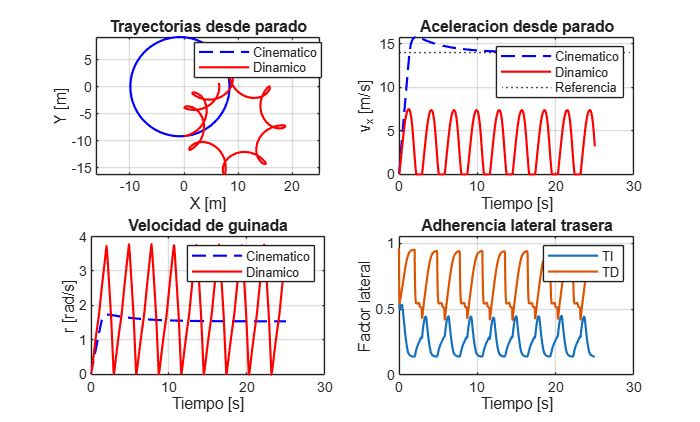


--- SKIDPAD DESDE PARADO ---
Reduccion lateral maxima: 86.2 %


        else
            tau = p.tau_brake_rec;
        end
        factor = 1-exp(-dt/tau);

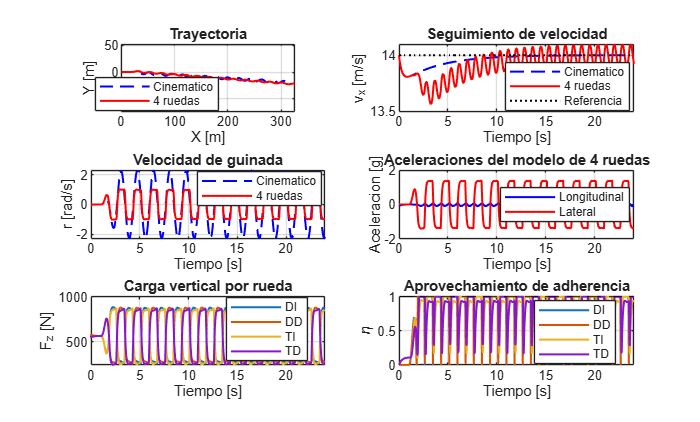

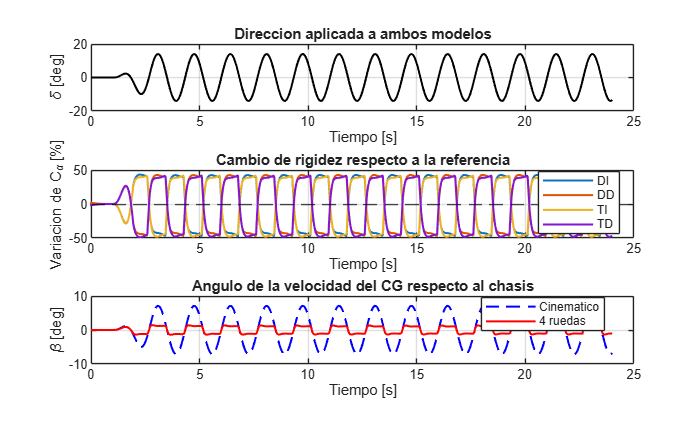


--- Eslalon ---
Carga minima por rueda [N]:
  253.4568  253.4403  248.1875  243.8460

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 87.3 %
Error maximo de equilibrio vertical: 0.000e+00 N


        eta_brake(i) = eta_brake_prev(i) + factor*(eta_brake_obj(i)-eta_brake_prev(i));
    end
    eta_brake = max(p.brake_slide_ratio,min(1,eta_brake));


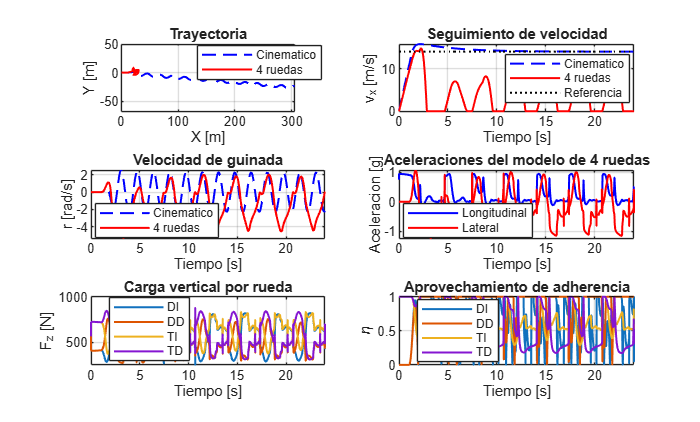

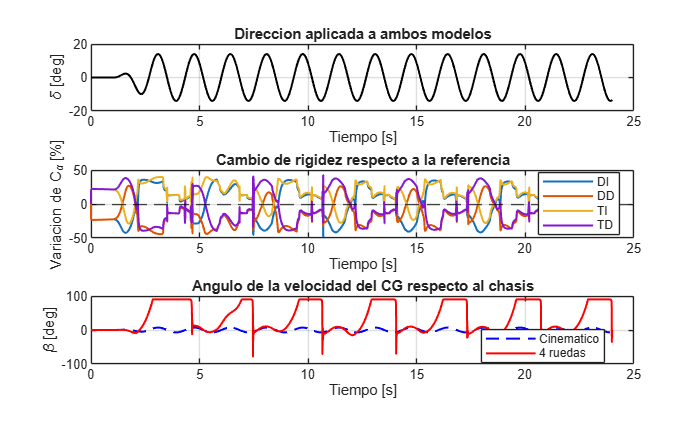


--- Eslalon desde parado ---
Carga minima por rueda [N]:
  249.8709  271.4997  368.3012  299.2440

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 100.0 %
Error maximo de equilibrio vertical: 4.547e-13 N


%% Friction circle with effective capacity

% The loss modifies the combined Fx/Fy limit only once.

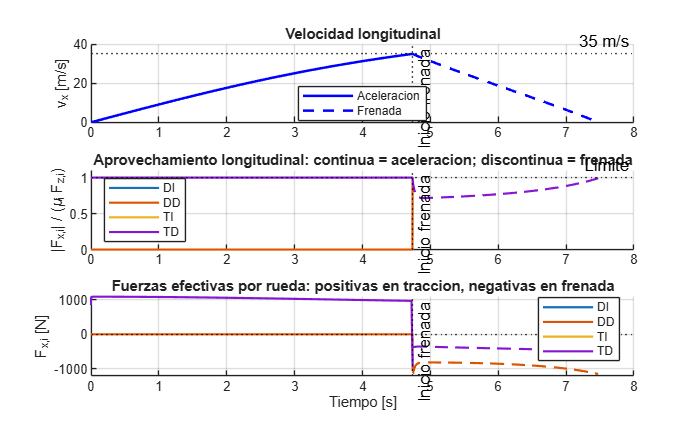

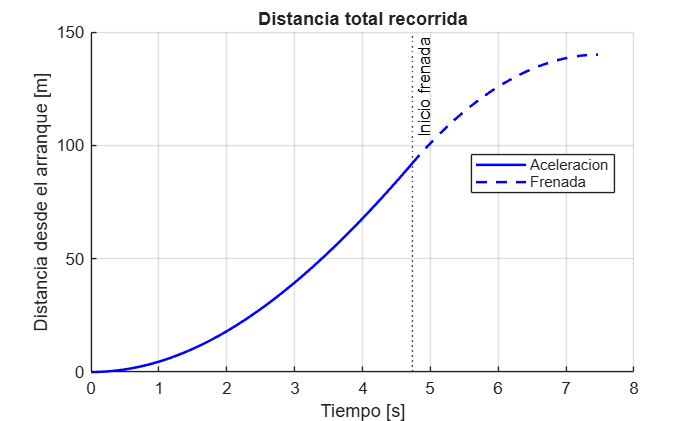

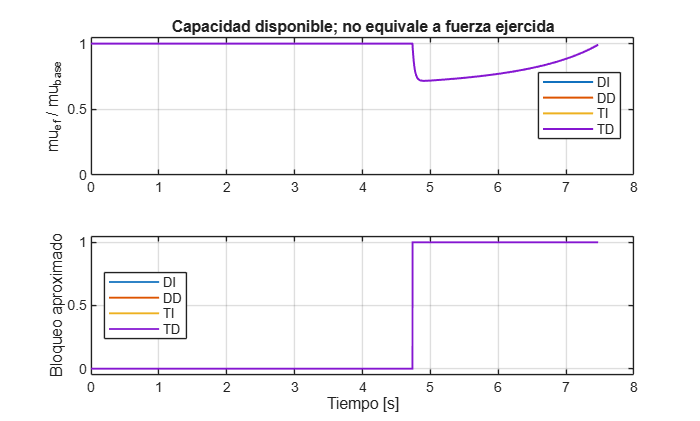


--- ACELERACION Y FRENADA EN RECTA ---
Velocidad maxima registrada: 35.002 m/s
Tiempo acelerando: 4.738 s
Tiempo de frenada registrado: 2.734 s
Distancia de frenada: 47.779 m
Velocidad final: 0.0033 m/s
Saturacion no equivale a bloqueo: no se modela rotacion de ruedas.
Las curvas izquierda/derecha coinciden por simetria en recta.


Fmax_w = eta_brake .* Fmax_peak_w;



--- Giro leve (2 grados) ---
Aceleracion: 4.738 s; frenada: 2.734 s; distancia frenada: 47.777 m
Inicio del giro: 4.025 m despues de empezar a frenar
Maxima fuerza lateral absoluta por rueda [N]: 0.000 0.000 0.000 0.000 

--- Giro acusado (10 grados) ---
Aceleracion: 4.738 s; frenada: 2.732 s; distancia frenada: 47.732 m
Inicio del giro: 4.025 m despues de empezar a frenar
Maxima fuerza lateral absoluta por rueda [N]: 0.000 0.000 0.000 0.000 


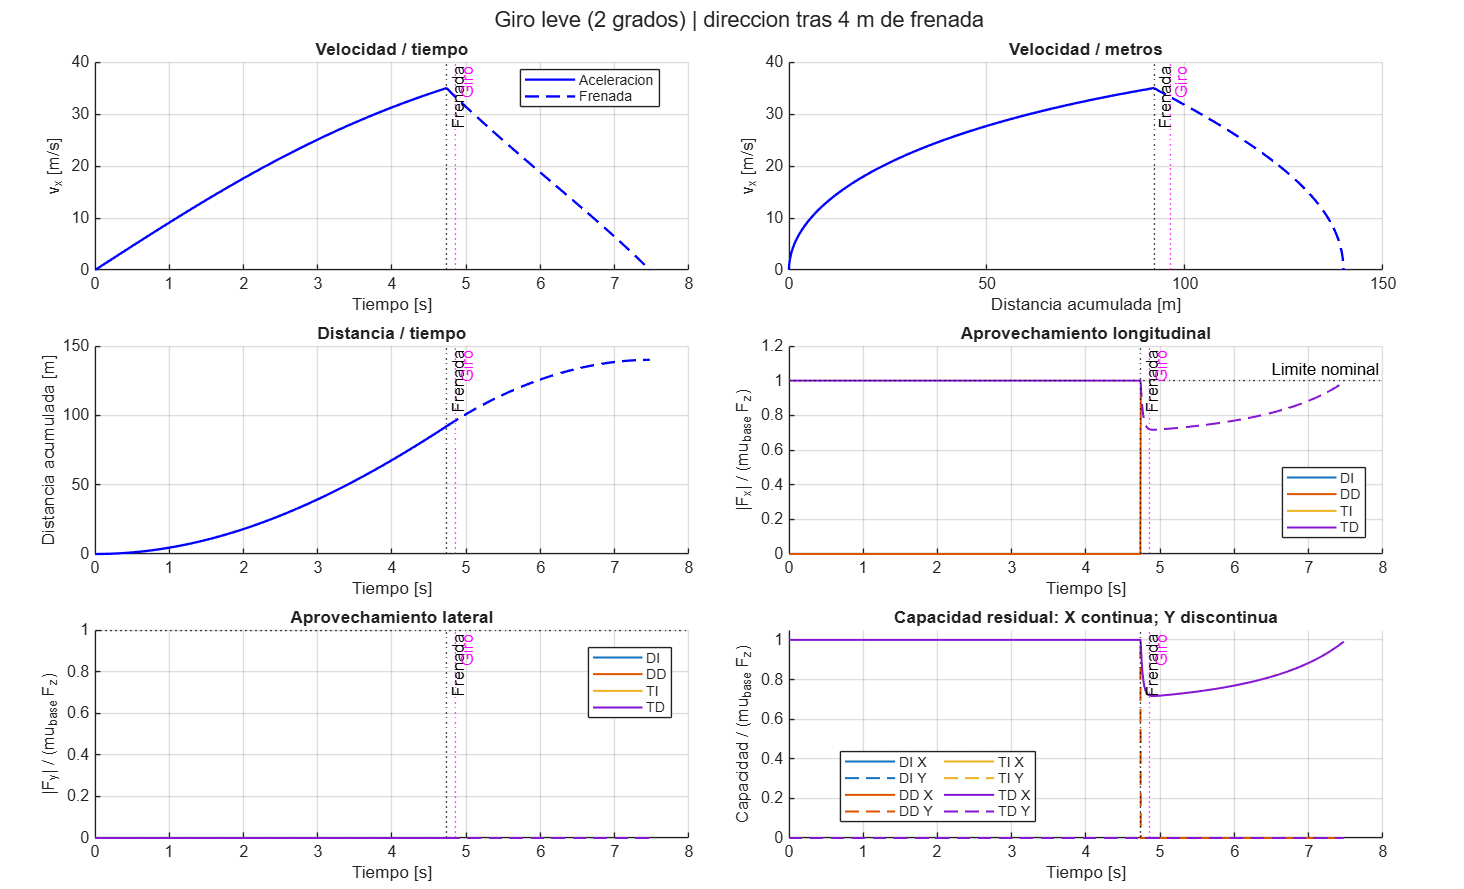

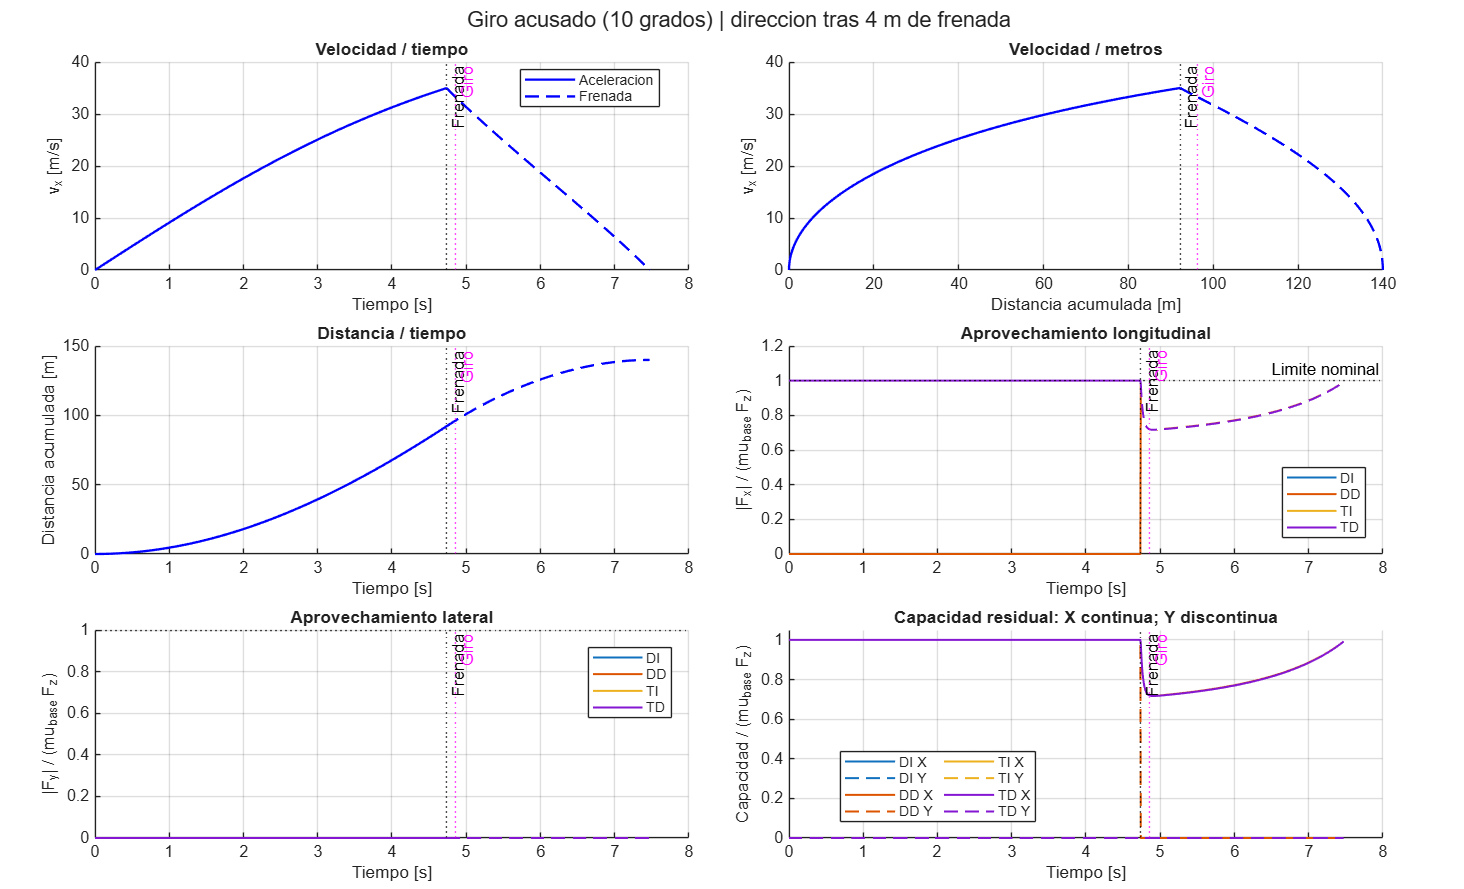

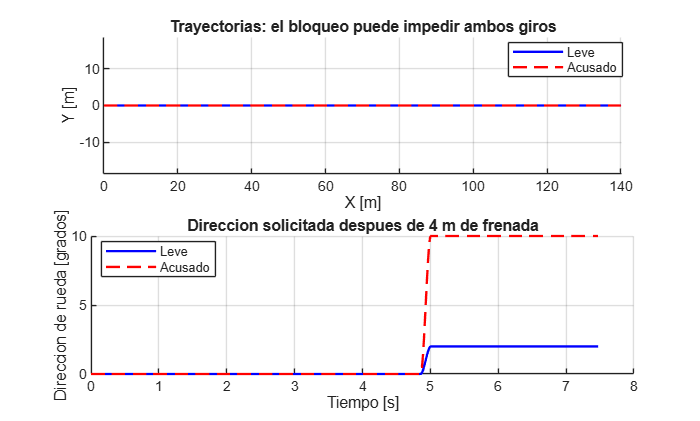

% Extension of the existing lock mode (simplified model):
% unit longitudinal factor: preserves the calculated mu_eff*Fz limit.

% zero lateral factor: removes Fy demand BEFORE circle saturation.
factor_x_bloqueo = ones(1,4);
factor_y_bloqueo = double(~bloqueo_w);
Fyw = factor_y_bloqueo .* Fyw;

Fres_w = hypot(Fxw_sol,Fyw);
lambda_w = min(ones(1,4), ...
    Fmax_w ./ max(Fres_w,eps));

Fxw = lambda_w .* Fxw_sol;
Fyw = lambda_w .* Fyw;

    
    %% Progressive lateral adhesion loss and recovery

    % Excess longitudinal demand relative to adhesion
    s_w = max(0, abs(Fxw_sol) ./ max(Fmax_w,eps) - 1);

    % Target lateral-capacity factor
    eta_obj = ones(1,4);

    % Additional loss is only triggered during driving
    if Fx > 0
        eta_obj(3:4) = 1 ./ (1 + p.Kslip .* s_w(3:4));
    end

    % Adhesion state inherited from the previous step
    eta_slip = eta_prev;

    % Rear-wheel time update
    for i = 3:4

        % Rapid loss or slow recovery
        if eta_obj(i) < eta_prev(i)
            tau = p.tau_slip_loss;
        else
            tau = p.tau_slip_rec;
        end

        % Stable exponential integration
        factor = 1 - exp(-dt/tau);

        eta_slip(i) = eta_prev(i) + factor * (eta_obj(i) - eta_prev(i));

    end

    % Bound the factor to its physically defined interval
    eta_slip = max(0,min(1,eta_slip));

    % Rear lateral-force reduction
    Fyw(3:4) = eta_slip(3:4) .* Fyw(3:4);

    % In lock mode, braking acts exclusively along CHASSIS X.
    % Removing only local Fy would still allow steering through Fx*sin(delta).
    % Outside lock mode, retain the original transformation.
    % This is a simplified restriction, not isotropic locked-wheel friction.
    delta_fuerza_w = delta_w;
    delta_fuerza_w(bloqueo_w) = 0;
    Fxw_chasis = Fxw .* cos(delta_fuerza_w) - Fyw .* sin(delta_fuerza_w);
    Fyw_chasis = Fxw .* sin(delta_fuerza_w) + Fyw .* cos(delta_fuerza_w);

    % Resultant forces and moment
    SumFx = sum(Fxw_chasis); % Total longitudinal force
    SumFy = sum(Fyw_chasis); % Total lateral force
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Yaw moment about the CG

    % Telemetry: current-step data without changing forces or dynamics
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Caw = Caw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_fuerza_w)) - p.yw .* (Fxw .* cos(delta_fuerza_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;
    tele.s_w = s_w;
    tele.eta_slip = eta_slip;
    tele.eta_obj = eta_obj;
    tele.Fmax_peak_w = Fmax_peak_w;
    tele.s_brake_w = s_brake_w;
    tele.eta_brake = eta_brake;
    tele.eta_brake_obj = eta_brake_obj;
    tele.bloqueo_w = bloqueo_w;
    tele.mu_eff_w = p.muw .* eta_brake;
    tele.factor_x_bloqueo = factor_x_bloqueo;
    tele.factor_y_bloqueo = factor_y_bloqueo;
    tele.delta_fuerza_w = delta_fuerza_w;
    tele.Fxw_chasis = Fxw_chasis;
    tele.Fyw_chasis = Fyw_chasis;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % equations of motion
    ax_fis = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m;
    ay_fis = SumFy/p.m;
    ax  = ax_fis + vy*r; % retain centripetal coupling
    ay = ay_fis - vx*r; 
    dr = SumMz/p.Iz;   
    tele.ax = ax_fis;
    tele.ay = ay_fis;

    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next; ...
        ax_fis; ay_fis; eta_slip(:); eta_brake(:); double(bloqueo_w(:))]; 
end


### Speed controller

% PI speed controller with the same force saturation as P1
ctrl.v_skid = 14; % [m/s] originally 5 (18 km/h), changed to 8 to compare responses
ctrl.Kp = 800; 
ctrl.Ki = 200;

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx;
    e_int = e_int + e*dt;

    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % PI
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); % kinematic-model saturation
end


### Test-track geometry

Simulate the simplified skidpad: 2.5 laps around a constant-radius circle with a 15.25 m inner radius and a 3 m wide lane. Complete the trajectory as quickly as possible without leaving the lane. Only the second lap is timed.

%% SKIDPAD TEST SIMULATOR [DO NOT MODIFY]
geom.R_in = 15.25/2; % inner radius (blue cones) [m]
geom.R_out = geom.R_in + 3; % outer radius (yellow cones; 3 m lane) [m]
geom.R = (geom.R_in + geom.R_out)/2; % centreline radius [m]

function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
    N = round(Tmax/dt);  z = z0;  e_int = 0;

    L = p.ld + p.lt;
    delta = atan(L/geom.R); 
    hist.t=zeros(1,N); hist.X=zeros(1,N); hist.Y=zeros(1,N); hist.psi=zeros(1,N);
    hist.vx=zeros(1,N); hist.vy=zeros(1,N); hist.r=zeros(1,N);
    hist.af=zeros(1,N); hist.ar=zeros(1,N);
    % New telemetry for the four-wheel dynamic model only
    es4R = strcmp(func2str(modelo), 'pasoDinamico');
    if es4R
        z = inicializarEstadoDinamico(z);
        hist.alpha_w = zeros(N,4);
        hist.Fxw = zeros(N,4);
        hist.Fyw = zeros(N,4);
        hist.Fzw = zeros(N,4);
        hist.Mzw = zeros(N,4);
        hist.Mz_long = zeros(1,N);
        hist.Mz_lat = zeros(1,N);
        hist.lambda_w = zeros(N,4);
        hist.Fmax_w = zeros(N,4);
        hist.s_w = zeros(N,4);
        hist.eta_slip = ones(N,4);
        hist.eta_brake = ones(N,4);
        hist.s_brake_w = zeros(N,4);
        hist.Fmax_peak_w = zeros(N,4);
    hist.bloqueo_w = false(N,4);
    hist.mu_eff_w = zeros(N,4);
    end
    hist.z = zeros(N,numel(z));
    for k = 1:N
        [Fx, e_int] = controlLongitudinal(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        u = [Fx; delta];
        vx_c = max(z(4), 1.0);
        hist.af(k) = delta - (z(5) + p.ld*z(6))/vx_c;
        hist.ar(k) =       - (z(5) - p.lt*z(6))/vx_c;
        if es4R
            [z, tele] = modelo(z, u, p, dt);
            hist.alpha_w(k,:) = tele.alpha_w;
            hist.Fxw(k,:) = tele.Fxw;
            hist.Fyw(k,:) = tele.Fyw;
            hist.Fzw(k,:) = tele.Fzw;
            hist.Mzw(k,:) = tele.Mzw;
            hist.Mz_long(k) = tele.Mz_long;
            hist.Mz_lat(k) = tele.Mz_lat;
            hist.lambda_w(k,:) = tele.lambda_w;
            hist.Fmax_w(k,:) = tele.Fmax_w;
            hist.s_w(k,:) = tele.s_w;
            hist.eta_slip(k,:) = tele.eta_slip;
            hist.eta_brake(k,:) = tele.eta_brake;
            hist.s_brake_w(k,:) = tele.s_brake_w;
            hist.Fmax_peak_w(k,:) = tele.Fmax_peak_w;
        hist.bloqueo_w(k,:) = tele.bloqueo_w;
        hist.mu_eff_w(k,:) = tele.mu_eff_w;



        else
            z = modelo(z, u, p, dt);
        end
        hist.t(k)=(k-1)*dt; hist.X(k)=z(1); hist.Y(k)=z(2); hist.psi(k)=z(3);
        hist.vx(k)=z(4); hist.vy(k)=z(5); hist.r(k)=z(6);
        hist.z(k,:) = z.';
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));                  
    hist.tVueltas = zeros(1, max(0, max(nV)));        
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end

function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: second lap = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: does not complete 2 laps within Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (leaves the track!)'); end
    fprintf('\n');
end

### Simulation

z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0]; % initial race-car state

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % approximately 2.5 laps; the second is timed

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6));

### Results

Expected response: the kinematic model follows a circle of about 9 m radius from geometry alone; the dynamic model follows a slightly larger radius because of understeer. Small slip angles and both axles' cornering stiffness determine this mild understeer. These descriptive values are retained from the original exercise.

%% SKIDPAD RESULTS

% Call the results subroutine

Simulacion_skidpad(histCin, histDin, p, geom, Rcin, Rdin, @informarVueltas);

%% SKIDPAD FROM REST

[histSkid0Cin, histSkid0Din] = Simulacion_skidpad_parado(p, ctrl, geom, dt, @simularE2, @pasoCinematico, @pasoDinamico);

%% SLALOM

[histEslalonCin, histEslalonDin] = Simulacion_eslalon(p, ctrl, @simularManiobra, @mostrarManiobra);
%% SLALOM FROM REST

[histEslalon0Cin, histEslalon0Din] = Simulacion_eslalon_parado(p, ctrl, @simularManiobra, @mostrarManiobra);

histRecta = Simulacion_aceleracion_frenada(p, dt, @pasoDinamico);
%% BRAKING WITH STEERING AFTER 4 METRES
[histGiroLeve, histGiroAcusado] = Simulacion_frenada_giro(p, dt, @pasoDinamico);

function z = inicializarEstadoDinamico(z)
    % Preserve memory when a complete state is supplied.
    z = z(:);
    if numel(z) == 6
        z = [z; zeros(2,1); ones(4,1); ones(4,1); zeros(4,1)];
    elseif numel(z) ~= 20
        error('Dynamic state: 6 or 20 components are required.');
    end
end

function hist = simularManiobra(p, ctrl, dt, caso, tipo, dinamico)

N = round(caso.T/dt);
z = [0; 0; 0; caso.v0; 0; 0];
if dinamico
    z = inicializarEstadoDinamico(z);
end

e_int = 0;


hist.t = (0:N-1)'*dt;
hist.z = zeros(N,numel(z));
hist.vref = zeros(N,1);
hist.delta = zeros(N,1);
hist.Fx_cmd = zeros(N,1);

if dinamico
    hist.Fzw = zeros(N,4);
    hist.Caw = zeros(N,4);
    hist.eta = zeros(N,4);
    hist.ax = zeros(N,1);
    hist.ay = zeros(N,1);
    hist.lambda_w = zeros(N,4);
    hist.s_w = zeros(N,4);
    hist.eta_slip = ones(N,4);
    hist.eta_brake = ones(N,4);
    hist.s_brake_w = zeros(N,4);
    hist.Fmax_peak_w = zeros(N,4);
    hist.bloqueo_w = false(N,4);
    hist.mu_eff_w = zeros(N,4);
end

for k = 1:N
    t = hist.t(k);

    if tipo == 1
        % Corner entry between 1 and 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = caso.delta*entrada;

        % 0-4 s: 5 m/s
        % 4-8 s: progressively increase to 8 m/s
        % 8-11 s: 8 m/s
        % 11-14 s: progressively decrease to 5 m/s
        % 14-20 s: 5 m/s
        subida = min(max((t-4)/4,0),1);
        bajada = min(max((t-11)/3,0),1);

        vref = 5 + 3*subida - 3*bajada;

    else
        % Smooth slalom entry between 1 and 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = entrada*caso.amplitud * sin(2*pi*caso.frecuencia*(t-1));

        
        % Speed reference independent of initial speed
        if isfield(caso,'vobjetivo')
            vref = caso.vobjetivo;
        else
            vref = caso.v0;
        end

    end

    [Fx, e_int] = controlLongitudinal(vref, z(4), e_int, dt, ctrl, p);

    u = [Fx; delta];

    % States and inputs at the start of the step
    hist.z(k,:) = z.';
    hist.vref(k) = vref;
    hist.delta(k) = delta;
    hist.Fx_cmd(k) = Fx;

    if dinamico
        [z_next, tele] = pasoDinamico(z, u, p, dt);

        hist.Fzw(k,:) = tele.Fzw;
        hist.Caw(k,:) = tele.Caw;

        hist.eta(k,:) = hypot(tele.Fxw,tele.Fyw)./ max(tele.Fmax_w,eps);

        hist.ax(k) = tele.ax;
        hist.ay(k) = tele.ay;
        hist.lambda_w(k,:) = tele.lambda_w;
        hist.s_w(k,:) = tele.s_w;
        hist.eta_slip(k,:) = tele.eta_slip;
        hist.eta_brake(k,:) = tele.eta_brake;
        hist.s_brake_w(k,:) = tele.s_brake_w;
        hist.Fmax_peak_w(k,:) = tele.Fmax_peak_w;
        hist.bloqueo_w(k,:) = tele.bloqueo_w;
        hist.mu_eff_w(k,:) = tele.mu_eff_w;



    else
        z_next = pasoCinematico(z, u, p, dt);
    end

    z = z_next;
end
end
function mostrarManiobra(cin, din, p, nombre)

t = din.t;
ruedas = {'DI','DD','TI','TD'};

figure('Name',nombre,'Color','w');

subplot(3,2,1)
plot(cin.z(:,1),cin.z(:,2),'b--', ...
    din.z(:,1),din.z(:,2),'r','LineWidth',1.2);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trajectory');
legend('Kinematic','Four wheels','Location','best');

subplot(3,2,2)
plot(t,cin.z(:,4),'b--', ...
    t,din.z(:,4),'r', ...
    t,din.vref,'k:','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('v_x [m/s]');
title('Speed tracking');
legend('Kinematic','Four wheels','Reference','Location','best');

subplot(3,2,3)
plot(t,cin.z(:,6),'b--', ...
    t,din.z(:,6),'r','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('r [rad/s]');
title('Yaw rate');
legend('Kinematic','Four wheels','Location','best');

subplot(3,2,4)
plot(t,din.ax/p.g,'b', ...
    t,din.ay/p.g,'r','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('Acceleration [g]');
title('Four-wheel-model accelerations');
legend('Longitudinal','Lateral','Location','best');

subplot(3,2,5)
plot(t,din.Fzw,'LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('F_z [N]');
title('Vertical wheel load');
legend(ruedas,'Location','best');

subplot(3,2,6)
plot(t,din.eta,'LineWidth',1.2);
yline(1,'k--','Limit');
grid on;
xlabel('Time [s]'); ylabel('\eta');
title('Adhesion utilization');
legend(ruedas,'Location','best');

% Second figure: tyre inputs and response
figure('Name',[nombre ' - Steering and stiffness'],'Color','w');

subplot(3,1,1)
plot(t,rad2deg(din.delta),'k','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('\delta [deg]');
title('Steering applied to both models');

subplot(3,1,2)
plot(t,100*(din.Caw./p.Caw - 1),'LineWidth',1.2);
yline(0,'k--');
grid on;
xlabel('Time [s]'); ylabel('C_\alpha variation [%]');
title('Stiffness change relative to reference');
legend(ruedas,'Location','best');

subplot(3,1,3)
betaCin = atan2(cin.z(:,5),cin.z(:,4));
betaDin = atan2(din.z(:,5),din.z(:,4));

plot(t,rad2deg(betaCin),'b--', t,rad2deg(betaDin),'r','LineWidth',1.2);
grid on;
xlabel('Time [s]'); ylabel('\beta [deg]');
title('CG velocity angle relative to chassis');
legend('Kinematic','Four wheels','Location','best');

fprintf('\n--- %s ---\n',nombre);
fprintf('Minimum load per wheel [N]:\n');
disp(min(din.Fzw,[],1));

fprintf('Maximum utilization per wheel:\n');
disp(max(din.eta,[],1));

fprintf('Time with at least one saturated wheel: %.1f %%\n', 100*mean(any(din.lambda_w < 1-1e-6,2)));

fprintf('Maximum vertical-equilibrium error: %.3e N\n', max(abs(sum(din.Fzw,2)-p.m*p.g)));
end

The kinematic model follows a constant-radius circle without slip, while the dynamic model follows a slightly larger circle at the same steering angle because of understeer. The original exercise reports approximately 0.55 g lateral acceleration for both.

In Formula Student, skidpad time measures maximum lateral-acceleration performance. Automotive constant-radius tests also measure the understeer gradient.